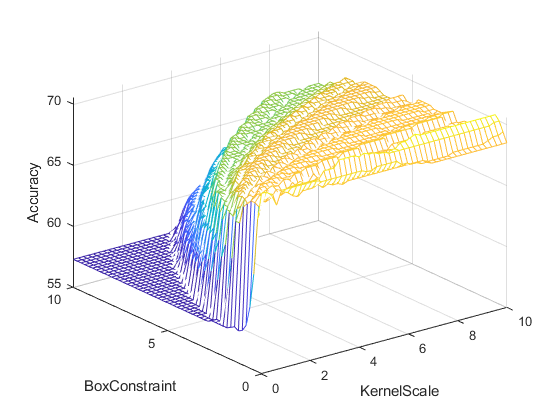

ans = 32×3 table
    Character    Validation_Accuracy    Testing_Accuracy
    _________    ___________________    ________________

      {'2'}             55.35                  63.8     
      {'3'}            56.681                61.355     
      {'4'}            59.283                 63.83     
      {'5'}            67.647                68.605     
      {'6'}            68.026                73.185     
      {'7'}            60.189                68.313     
      {'8'}            57.255                62.915     
      {'9'}            52.308                59.717     
      {'A'}             52.34                56.762     
      {'B'}            62.695                57.042     
      {'C'}            63.655                68.952     
      {'D'}            59.007                57.884     
      {'E'}            63.305                59.341     
      {'F'}            61

ans = 15.9943

characc = 10.2764

wordacc = 0

Array indices must be positive integers or logical values.

clear all;
if ~isfile('S_net.mat')
    if ~isfile('features_labels.mat')
        load('character_info_SVM.mat')
        N = size(char_imgs,2);
        features = zeros(N,72);
        labels = cell2mat(char_labels);
        for i=1:N
            features(i,:) = extractHOGFeatures(char_imgs{i});
        end
        rng(22);
        idx = randperm(N);
        
        idx_train = idx(1:N*.6);
        idx_val = idx(N*.6:N*.8);
        idx_test = idx(N*.8:N);
        
        features_train = features(idx_train,:);
        features_val = features(idx_val,:);
        features_test = features(idx_test,:);
        
        labels_train = labels(idx_train);
        labels_val = labels(idx_val);
        labels_test = labels(idx_test);
        
        save('features_labels.mat', 'features_train','features_val','features_test','labels_train','labels_val','labels_test')
    else
        load('features_labels.mat')
    end
    
    char_ls = unique(labels_train);
    N = size(char_ls,2);
    chars = {};
    val_accs = zeros(N,1);
    test_accs = zeros(N,1);
 
    c = 'G';
    
    p = 50;
    x = linspace(0.01,10,p);
    y = linspace(0.01,10,p);
    z = zeros(p);
    
    best_acc = 0;
    best_ks = 0;
    best_bc = 0;
    
    target_train = zeros(sum(labels_train == c)*2, 1);
    target_train(1:sum(labels_train == c)) = find(labels_train == c);
    id_not = find(labels_train ~= c);
    target_train(sum(labels_train == c)+1:sum(labels_train == c)*2) = id_not(1:sum(labels_train == c));
    features_train_t = features_train(target_train);
    labels_train_t = labels_train(target_train);
    
    target_val = zeros(sum(labels_val == c)*2, 1);
    target_val(1:sum(labels_val == c)) = find(labels_val == c);
    id_not = find(labels_val ~= c);
    target_val(sum(labels_val == c)+1:sum(labels_val == c)*2) = id_not(1:sum(labels_val == c));
    features_val_t = features_val(target_val);
    labels_val_t = labels_val(target_val);
    
    target_test = zeros(sum(labels_test == c)*2, 1);
    target_test(1:sum(labels_test == c)) = find(labels_test == c);
    id_not = find(labels_test ~= c);
    target_test(sum(labels_test == c)+1:sum(labels_test == c)*2) = id_not(1:sum(labels_test == c));
    features_test_t = features_test(target_test);
    labels_test_t = labels_test(target_test);
       
    target_train = ((labels_train_t==c).*2)-1;
    target_val = ((labels_val_t==c).*2)-1;
    target_test = ((labels_test_t==c).*2)-1;
    count_char = sum(labels_train_t==c);
    
    for i = 1:p
        for j = 1:p
            net = fitcsvm(features_train_t,target_train,'KernelFunction','RBF', 'Standardize',false, ...
            'ClassNames',[-1, 1], 'KernelScale', x(i), 'BoxConstraint', y(j));
            [detectedClasses, distances] = predict(net, features_val_t);
            truePos_trueNeg = sum((target_val + detectedClasses.') == 2) + sum((target_val + detectedClasses.') == -2);
            z(i,j) = truePos_trueNeg/size(target_val,2)*100;
            if z(i,j) >= best_acc
                best_acc = z(i,j);
                best_ks = x(i);
                best_bc = y(j);
            end
        end
    end

    nets = cell(N,1);
    for i=1:N
        c = char_ls(i);
        chars = [chars,c];
        
        target_train = zeros(sum(labels_train == c)*2, 1);
        target_train(1:sum(labels_train == c)) = find(labels_train == c);
        id_not = find(labels_train ~= c);
        target_train(sum(labels_train == c)+1:sum(labels_train == c)*2) = id_not(1:sum(labels_train == c));
        features_train_t = features_train(target_train);
        labels_train_t = labels_train(target_train);
        
        target_val = zeros(sum(labels_val == c)*2, 1);
        target_val(1:sum(labels_val == c)) = find(labels_val == c);
        id_not = find(labels_val ~= c);
        target_val(sum(labels_val == c)+1:sum(labels_val == c)*2) = id_not(1:sum(labels_val == c));
        features_val_t = features_val(target_val);
        labels_val_t = labels_val(target_val);
        
        target_test = zeros(sum(labels_test == c)*2, 1);
        target_test(1:sum(labels_test == c)) = find(labels_test == c);
        id_not = find(labels_test ~= c);
        target_test(sum(labels_test == c)+1:sum(labels_test == c)*2) = id_not(1:sum(labels_test == c));
        features_test_t = features_test(target_test);
        labels_test_t = labels_test(target_test);
        
        % Convert Boolean Arrays to -1 / +1 for SVM
        target_train = ((labels_train_t==c).*2)-1;
        target_val = ((labels_val_t==c).*2)-1;
        target_test = ((labels_test_t==c).*2)-1;
        
        
        testing = find(target_train == -1);
        
        net = fitcsvm(features_train_t,target_train,'KernelFunction','RBF', 'Standardize',true, ...
        'ClassNames',[-1, 1], 'KernelScale', best_ks, 'BoxConstraint', best_bc);
        [detectedClasses, distances] = predict(net, features_val_t);
        truePos_trueNeg = sum((target_val + detectedClasses.') == 2) + sum((target_val + detectedClasses.') == -2);
        val_acc = truePos_trueNeg/size(target_val,2)*100;
    
        %fprintf("Validation Accuracy for %s-SVM: %.3f\n", c, val_acc);
        
        [detectedClasses, distances] = predict(net, features_test_t);
        detectedClasses = transpose(detectedClasses);
        true_pos = sum(target_test+detectedClasses==2);
        false_neg = sum((target_test == 1).*(detectedClasses == -1));
        false_pos = sum((target_test == -1).*(detectedClasses == 1));
        true_neg = sum(target_test+detectedClasses==-2);
        total = true_pos + false_pos + false_neg + true_neg;
        test_acc = (true_pos + true_neg)/total*100;
        
        %fprintf("Testing Accuracy for %s-SVM: %.3f\n\n", c, test_acc);
        val_accs(i) = val_acc;
        test_accs(i) = test_acc;
        
        nets{i} = net;
    end
    
    figure;
    mesh(x,y,z);
    xlabel('KernelScale');
    ylabel('BoxConstraint');
    zlabel('Accuracy');
    
    Character = chars.';
    Validation_Accuracy = val_accs;
    Testing_Accuracy = test_accs;
    table(Character,Validation_Accuracy,Testing_Accuracy)
    
    m=sum(test_accs)/32;
    ((m/100)^4)*100
  
    
    path = "images/easy/";
    files_png = dir(fullfile(path,"*.png"));
    num_of_png_imgs = floor(numel(files_png)/10);
    images_png = {};
    
    wordCount = 0;
    charCount = 0;
    
    imgsucc = 0;
    imgfail = 0;
    
    for i = 1:num_of_png_imgs
        filepath = fullfile(path, files_png(i).name);
        str = strsplit(files_png(i).name, '.');
        imglabel = str{1};
        img = rgb2gray(imread(char(filepath)));
        [img1, img2, img3, img4] = charSeperator(img);
        images_png = [images_png, img1];
        images_png = [images_png, img2];
        images_png = [images_png, img3];
        images_png = [images_png, img4];
        
        newfeatures = zeros(4,72);
        
        for j=1:4
            newfeatures(j,:) = extractHOGFeatures(images_png{j});
        end
        
        
        
        
        maxDistance1 = 0;
        maxDistance2 = 0;
        maxDistance3 = 0;
        maxDistance4 = 0;
        class1 = '';
        class2 = '';
        class3 = '';
        class4 = '';
        
        for j = 1:N
            [detectedClasses, distances] = predict(nets{j}, newfeatures(:,1));
            if distances(1,2) > maxDistance1 && detectedClasses(1) == 1
                maxDistance1 = distances(1,2);
                class1 = chars{j};
            end
            if distances(2,2) > maxDistance2 && detectedClasses(2) == 1
                maxDistance2 = distances(2,2);
                class2 = chars{j};
            end
            if distances(3,2) > maxDistance3 && detectedClasses(3) == 1
                maxDistance3 = distances(3,2);
                class3 = chars{j};
            end
            if distances(4,2) > maxDistance4 && detectedClasses(4) == 1
                maxDistance4 = distances(4,2);
                class4 = chars{j};
            end
        end
        
        if class1 == imglabel(1)
            charCount = charCount + 1;
        end
        if class2 == imglabel(2)
            charCount = charCount + 1;
        end
        if class3 == imglabel(3)
            charCount = charCount + 1;
        end
        if class4 == imglabel(4)
            charCount = charCount + 1;
        end
        if class1 == imglabel(1) && class2 == imglabel(2) && class3 == imglabel(3) && class4 == imglabel(4)
            wordCount = wordCount + 1;
            imgsucc = i;
        else
            imgfail = i;
        end
    end
    
    
    characc = (charCount/(4*num_of_png_imgs))*100
    wordacc = (wordCount/num_of_png_imgs)*100
    
    succ = strsplit(files_png(imgsucc).name, '.')
    fail = strsplit(files_png(imgfail).name, '.')
    
    save('SVM_net.mat', 'nets', 'chars')
else
    load('SVM_net.mat')
end

function [img1, img2, img3, img4] = charSeperator(img)
    mask = img>=120;
    y = sum(255-mask.*255);
    bar(y);
    lm = islocalmin(y);
    w = -9999*(lm-1);
    [v,i] = mink(y+w,3);
    i = sort(i);
    img1 = imresize(img(:,1:i(1)),[24,18]);
    img2 = imresize(img(:,i(1):i(2)),[24,18]);
    img3 = imresize(img(:,i(2):i(3)),[24,18]);
    img4 = imresize(img(:,i(3):size(img,2)),[24,18]);
end